Task 1

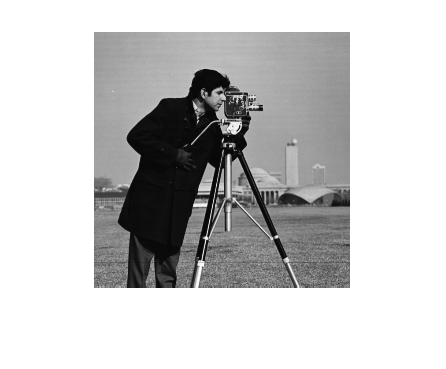

H1=[-1 -1 -1
    -1 8 -1
    -1 -1 -1];

H2=[-1 -1 -1
    -1 9 -1
    -1 -1 -1];

H3=[-1 -1 -1
    -1 9.7 -1
    -1 -1 -1];

% H4=[0 1 0
%     1 -4 1
%     0 1 0];

% H5=[1 4 1
%     4 -20 4
%     1 4 1];

% H6=[0 -1 0
%     -1 4 -1
%     0 -1 0];

I=imread("cameraman.tif");
figure()
imshow(I)

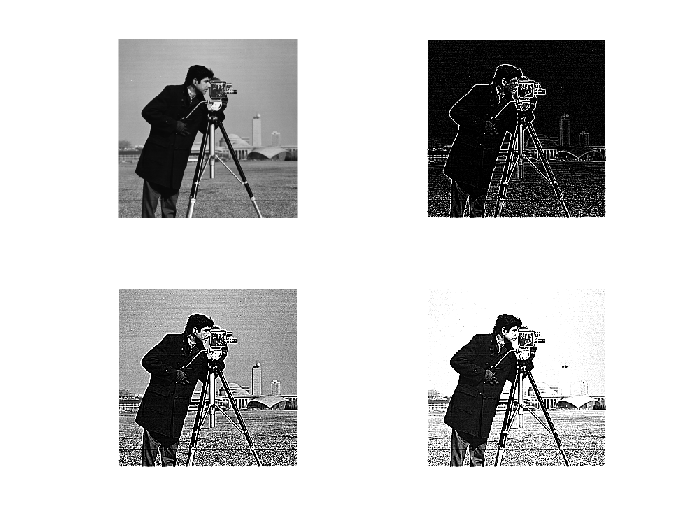


filteredImg1=imfilter(I,H1);
filteredImg2=imfilter(I,H2);
filteredImg3=imfilter(I,H3);
% 
% filteredImg4=imfilter(I,H4);
% filteredImg5=imfilter(I,H5);
% filteredImg6=imfilter(I,H6);

figure()
subplot(2,2,1), imshow(I)
subplot(2,2,2), imshow(filteredImg1)
subplot(2,2,3), imshow(filteredImg2)
subplot(2,2,4), imshow(filteredImg3)

Task 2

Inoisy=uint8(imnoise(I,'gaussian'));
disp("Real and noisy Image")

Real and noisy Image


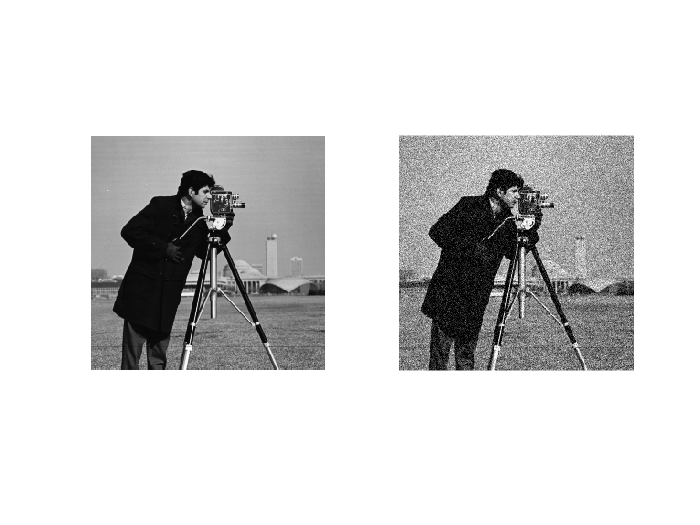

figure()
subplot(1,2,1), imshow(I);
subplot(1,2,2), imshow(Inoisy);

     3



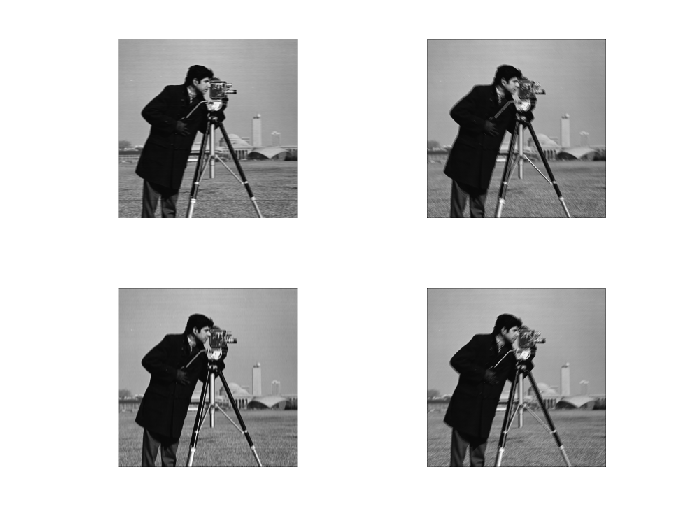

Part C


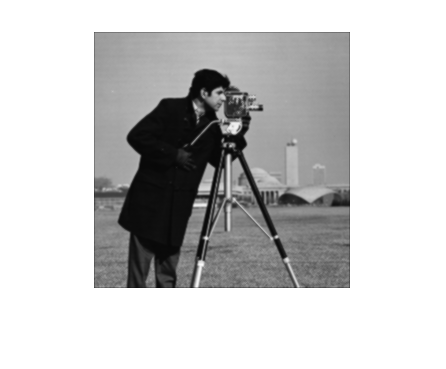

     5



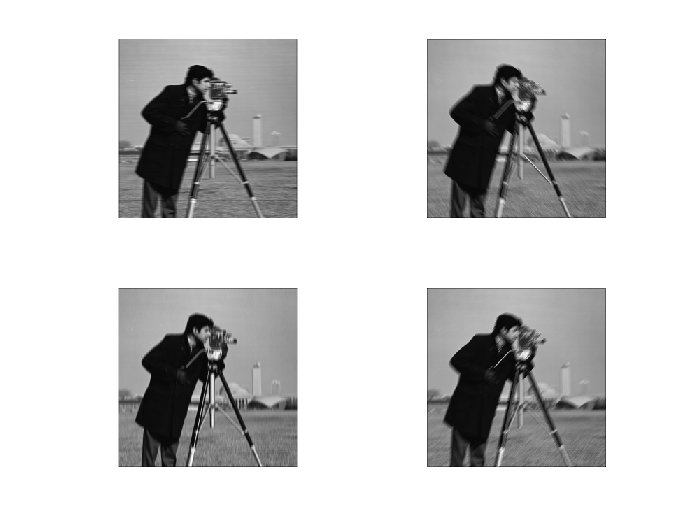

Part C


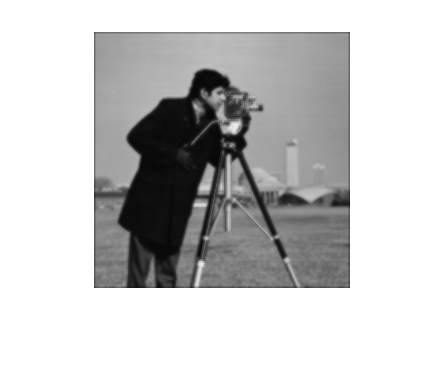

     7



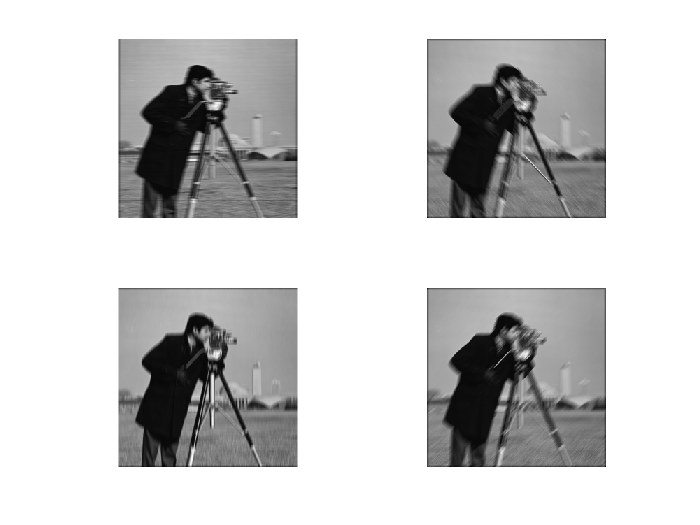

Part C


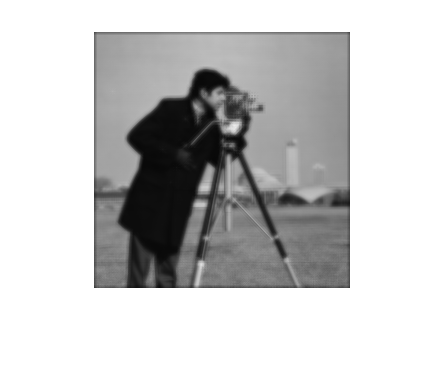


for n=3:2:7
    disp(n)
    directional_filtering(I,n)
end

Task 3

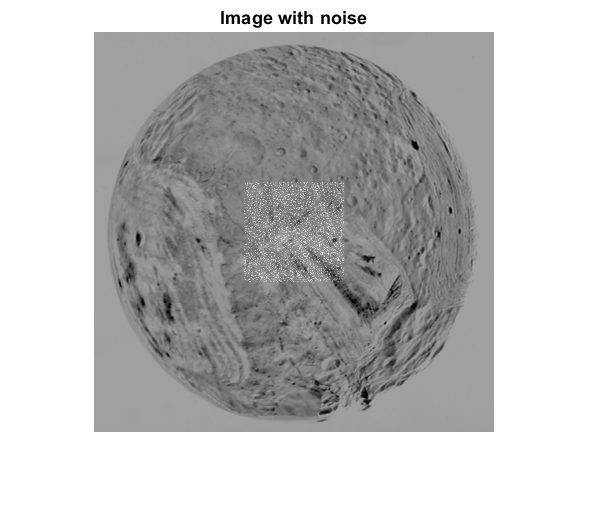

I=imread("miranda1.tif");
noise = uint8(randn(100)*40);

targetSize = [100 100];
win1 = centerCropWindow2d(size(I),targetSize);
I1=I;
I1(win1.XLimits(1):win1.XLimits(2), win1.YLimits(1):win1.YLimits(2), :) = I1(win1.XLimits(1):win1.XLimits(2), win1.YLimits(1):win1.YLimits(2), :)+ noise;
figure()
imshow(I1)
title('Image with noise')

     3



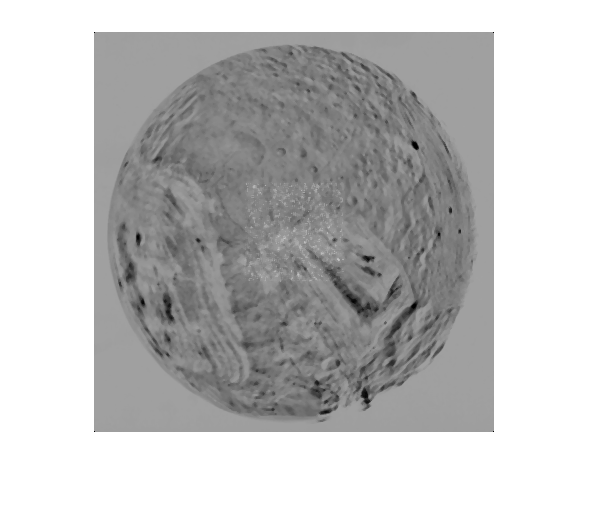

     5



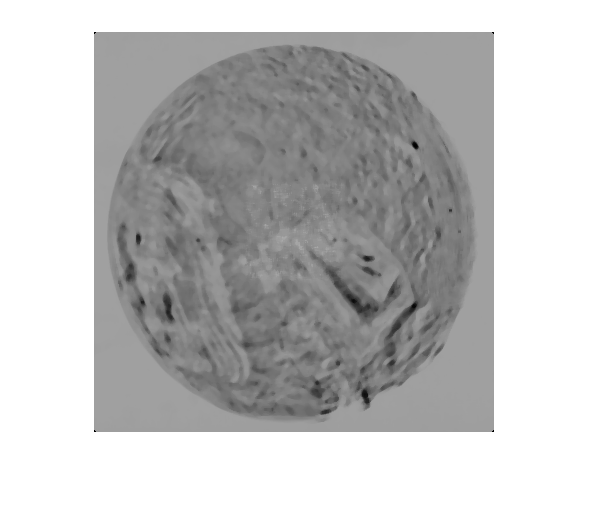

     7



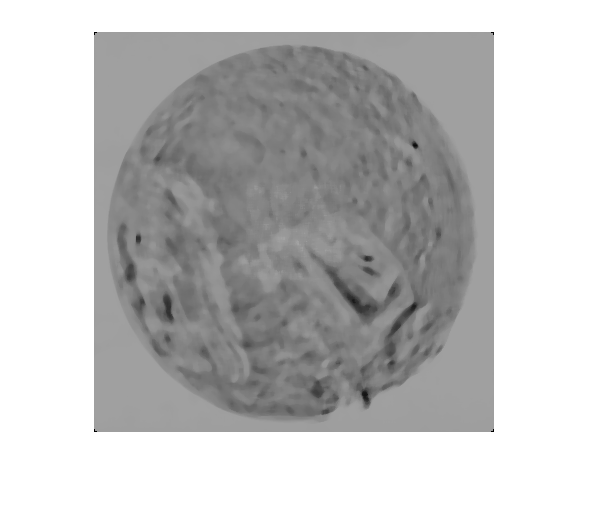


figure()
for n=3:2:7
    disp(n)
    medianFilteredImage=med_filter(I1,n);
    medianFilteredImage=uint8(medianFilteredImage);
    figure, imshow(medianFilteredImage)
    
end



figure()
medianFilteredImage=med_filter(I1,3);
medianFilteredImage=uint8(medianFilteredImage);

medianFilteredImage2=med_filter(I1,5);
medianFilteredImage2=uint8(medianFilteredImage2);

medianFilteredImage3=med_filter(I1,7);
medianFilteredImage3=uint8(medianFilteredImage3);

getImage=thresholdFunc(I1,medianFilteredImage);
getImage2=thresholdFunc(I1,medianFilteredImage2);
getImage3=thresholdFunc(I1,medianFilteredImage3);
disp("Noisy Image and Image after threshold filtering")

Noisy Image and Image after threshold filtering


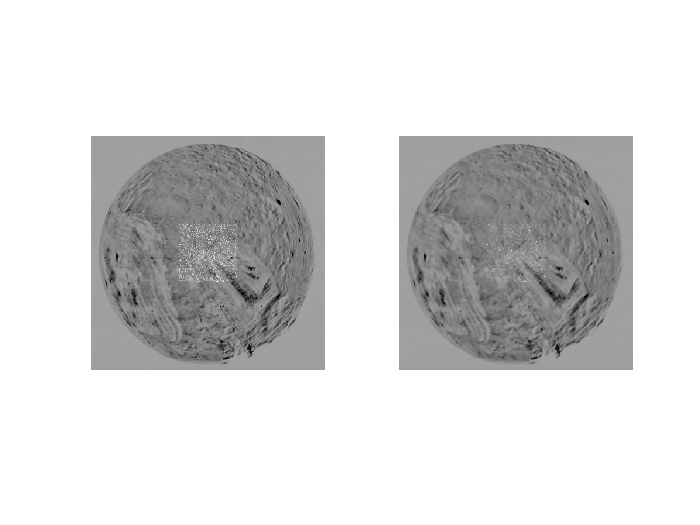

figure();
subplot(1,2,1), imshow(I1)
subplot(1,2,2), imshow(getImage)

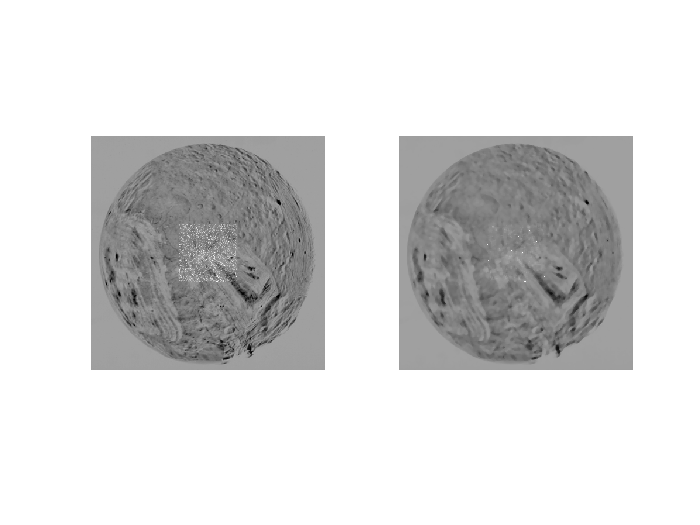

figure();
subplot(1,2,1), imshow(I1)
subplot(1,2,2), imshow(getImage2)

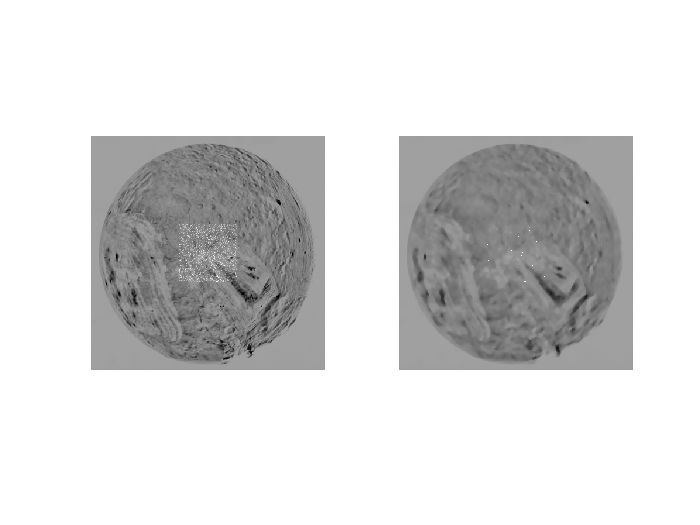

figure();
subplot(1,2,1), imshow(I1)
subplot(1,2,2), imshow(getImage3)

%imshow(getImage) 

function resultImage=thresholdFunc(I,O)
alpha=100;
getDiff=I-O;
a=getDiff>alpha;
a=uint8(a);
retrieveI=a.*I;

retrieveO=retrieveI==0;
retrieveO=uint8(retrieveO);
retrieveO=retrieveO.*O;

resultImage=retrieveI+retrieveO;
end

